# **Standing wave dispersion simulation **

clear
clc

`현재 위치 설정 및 경로추가

cd 'C:\Users\PC\OneDrive\UNIST\simulation\Standing wave dispersion\STN wave dispersion 3.0 20250703'
addpath 'C:\Users\PC\OneDrive\UNIST\simulation\Standing wave dispersion\STN wave dispersion 3.0 20250703\data'

랜덤 방식 설정

rng('shuffle'); % Seed the random number generator based on the current time

vx_tilt_list = [5.5:0.5:6.5]

vx_tilt_list =     5.5000    6.0000    6.5000


for vx_tilt_ind = 1:numel(vx_tilt_list)

기본 상수 설정

load("STN_constants.mat"); %load default constants
%you can re-define contants here!
vx_caused_tilted=vx_tilt_list(vx_tilt_ind)

vx_caused_tilted = 5.5000

vx_caused_tilted = 6

vx_caused_tilted = 6.5000

세기(I) 리스트 작성

%I1, I2 setting (I1과 I2의 행렬 크기를 같게 하세요.)

%1.2mJ
% I1_list = [0.1 0.2 0.3 0.4 0.6 1.2]*0.65;
% I2_list = [14.4 7.2 4.8 3.6 2.4 1.2]*0.65;

%1.4mJ
% I1_list = [0.1 0.2 0.4 0.5 0.7 0.8 1.4]*0.65;
% I2_list = [19.6 9.8 4.9 3.92 2.8 2.45 1.4]*0.65;

%1.6mJ
% I1_list = [0 0.1 0.2 0.25 0.4 0.8 1.6]*0.7;
% I2_list = [0 25.6 12.8 10.2 6.4 3.2 1.6]*0.7;

%SW
I1_list = [0:0.05:5];
I2_list = [0:0.05:5];

% off 
% I1_list = [0];
% I2_list = [0];
Cell_velocity=cell(numel(I2_list),1);

Trajectory calculation.

for I_ind = 1:numel(I2_list)
run('Main_code.m') %Main code returns the velocity of x,y,z
% run('Main_code_CUDA.m') %Main code returns the velocity of x,y,z
Cell_velocity{I_ind}=velocity;% Cell_velocity(intensity list) = velocity of particle, 
end

Elapsed time is 7.469920 seconds.
Elapsed time is 7.162741 seconds.
Elapsed time is 7.309439 seconds.
Elapsed time is 7.191737 seconds.
Elapsed time is 7.217437 seconds.
Elapsed time is 7.041057 seconds.
Elapsed time is 6.866185 seconds.
Elapsed time is 6.849878 seconds.
Elapsed time is 6.837980 seconds.
Elapsed time is 6.854644 seconds.
Elapsed time is 6.880550 seconds.
Elapsed time is 6.908317 seconds.
Elapsed time is 6.904867 seconds.
Elapsed time is 6.892943 seconds.
Elapsed time is 6.901843 seconds.
Elapsed time is 6.932100 seconds.
Elapsed time is 6.914954 seconds.
Elapsed time is 6.924930 seconds.
Elapsed time is 6.926210 seconds.
Elapsed time is 6.992729 seconds.
Elapsed time is 6.947047 seconds.
Elapsed time is 6.998301 seconds.
Elapsed time is 6.952899 seconds.
Elapsed time is 6.957705 seconds.
Elapsed time is 6.973311 seconds.
Elapsed time is 6.964674 seconds.
Elapsed time is 7.007906 seconds.
Elapsed time is 6.978466 seconds.
Elapsed time is 6.959397 seconds.
Elapsed time i

Elapsed time is 6.887848 seconds.
Elapsed time is 7.307811 seconds.
Elapsed time is 7.283247 seconds.
Elapsed time is 7.346189 seconds.
Elapsed time is 7.329225 seconds.
Elapsed time is 7.253527 seconds.
Elapsed time is 7.378169 seconds.
Elapsed time is 7.353807 seconds.
Elapsed time is 7.352415 seconds.
Elapsed time is 7.399397 seconds.
Elapsed time is 7.374756 seconds.
Elapsed time is 7.382630 seconds.
Elapsed time is 7.430439 seconds.
Elapsed time is 7.371360 seconds.
Elapsed time is 7.400634 seconds.
Elapsed time is 7.371846 seconds.
Elapsed time is 7.443365 seconds.
Elapsed time is 7.427816 seconds.
Elapsed time is 7.454476 seconds.
Elapsed time is 7.463790 seconds.
Elapsed time is 7.457990 seconds.
Elapsed time is 7.450836 seconds.
Elapsed time is 7.455766 seconds.
Elapsed time is 7.543833 seconds.
Elapsed time is 7.503654 seconds.
Elapsed time is 7.534900 seconds.
Elapsed time is 7.535293 seconds.
Elapsed time is 7.512259 seconds.
Elapsed time is 7.468647 seconds.
Elapsed time i

Elapsed time is 7.087715 seconds.
Elapsed time is 7.441156 seconds.
Elapsed time is 7.463601 seconds.
Elapsed time is 7.445269 seconds.
Elapsed time is 7.416756 seconds.
Elapsed time is 7.476281 seconds.
Elapsed time is 7.510008 seconds.
Elapsed time is 7.491114 seconds.
Elapsed time is 7.568429 seconds.
Elapsed time is 7.509434 seconds.
Elapsed time is 7.556402 seconds.
Elapsed time is 7.530263 seconds.
Elapsed time is 7.590242 seconds.
Elapsed time is 7.598936 seconds.
Elapsed time is 7.561481 seconds.
Elapsed time is 7.578293 seconds.
Elapsed time is 7.595721 seconds.
Elapsed time is 7.603904 seconds.
Elapsed time is 7.652364 seconds.
Elapsed time is 7.578844 seconds.
Elapsed time is 7.684239 seconds.
Elapsed time is 7.644639 seconds.
Elapsed time is 7.676731 seconds.
Elapsed time is 7.650469 seconds.
Elapsed time is 7.644071 seconds.
Elapsed time is 7.648905 seconds.
Elapsed time is 7.701017 seconds.
Elapsed time is 7.833338 seconds.
Elapsed time is 7.709214 seconds.
Elapsed time i

Image blurring 상수 설정

vel_pix=2.28; %픽셀당 속도
rep_std=4.0; %electron repulsion standard deviation
rep_vel=2.7; %electron repulsion speed standard deviation

Image blurring (z축 방향으로는 계산안함)

run('Image_code_voigt.m')

plotting

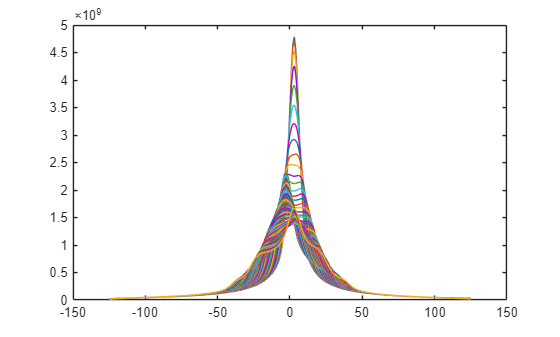

plot(xgrid,sumx)

Save

%making the data saved
constants = struct();
constants.I1_list = I1_list;
constants.I2_list = I2_list;
constants.lambda = lambda;
constants.MAX = MAX;
constants.tend = tend;
constants.tstep = tstep;
constants.vx_caused_tilted = vx_caused_tilted;
constants.vel_pix=vel_pix;
constants.Dye_sigma=Dye_sigma;
constants.w0z = w0z;
constants.w0y = w0y;
constants.jm_data  = jm_data;
constants.x_init_distribution = x_init_distribution;
constants.x_init_vel_sigma= x_init_vel_sigma;
constants.y_init_vel_sigma= y_init_vel_sigma; 
constants.z_init_vel_sigma = z_init_vel_sigma;
constants.z_init_vel_off = z_init_vel_off;
constants.Dye_tau=Dye_tau;
constants.Ips_z = Ips_z;
constants.Ips_y = Ips_y;
constants.Ij_distribution = Ij_distribution;

data = struct();
data.xgrid=xgrid';
data.ygrid=ygrid';
data.img_matrix=img_matrix;
data.sumx=sumx;
data.sumy=sumy;

filename=sprintf("data_SW_20251127_%2.0f.mat",vx_tilt_ind)

save(filename,'data','I1_list','I2_list','Cell_velocity','constants');

filename = "data_SW_20251127_ 1.mat"

filename = "data_SW_20251127_ 2.mat"

filename = "data_SW_20251127_ 3.mat"

end